% a) Compute the complex power at point 1 and 2 and power losses of the line
V2 = 100;                                % source V2 (V)
ZL = 0.5 + 7.5i;                         % line impedance (ohms)
magnitude = [90:120];                    % V1 magnitude from 75% (90) to 100% (120)
V1 = magnitude*(cosd(-5) + sind(-5)*i);  % source V1 (V)
VL = V1 - V2;                            % voltage across line impedance, ZL (V)
I12 = VL/ZL;                             % line current, I12 (A)
I21 = -I12;                              % line current, I21 (A)

P1 = real(V1.*conj(I12));        % real power delivered at point 1, Q1 (W)
Q1 = imag(V1.*conj(I12));        % reactive power delivered at point 1, Q1 (VAR)
P2 = real(V2.*conj(I21));        % real power delivered at point 2, Q2 (W)
Q2 = imag(V2.*conj(I21));        % reactive power delivered at point 2, Q2 (VAR)
PL = real(VL.*conj(I12));        % real power absorbed at line impedance (W)
QL = imag(VL.*conj(I12));        % reactive power absorbed at line impedance (VAR)


% b) Tabulate the reactive powers and plot Q1 Q2, QL, versus voltage magnitude V1.
T = table(rot90(magnitude, 3), rot90(Q1, 3), rot90(Q2, 3), rot90(QL, 3), 'VariableNames', {'V1 magnitude (V)', 'Q1 delivered (VAR)', 'Q2 delivered (VAR)', 'QL absorbed (VAR)'});
disp(T)

    V1 magnitude (V)    Q1 delivered (VAR)    Q2 delivered (VAR)    QL absorbed (VAR)
    ________________    __________________    __________________    _________________

           90                 -107.98               130.35               22.367      
           91                 -97.101               117.05               19.946      
           92                 -85.956               103.75                17.79      
           93                 -74.545               90.445                 15.9      
           94                 -62.869               77.144               14.275      
           95                 -50.927               63.843               12.916      
           96                  -38.72               50.542               11.822      
           97                 -26.247               37.241               10.994      
   

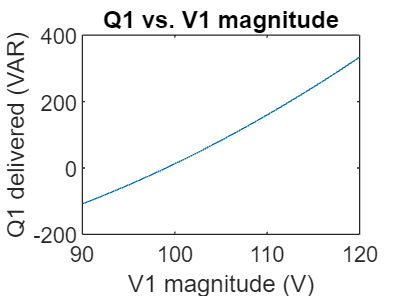


% Q1 vs. V1 plot
plot(magnitude, Q1)
title('Q1 vs. V1 magnitude')
xlabel('V1 magnitude (V)')
ylabel('Q1 delivered (VAR)')

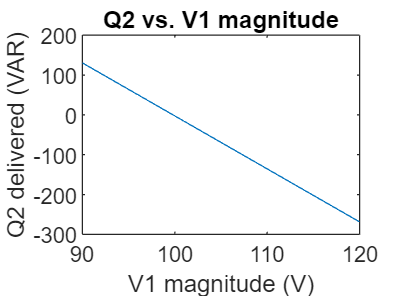

% Q2 vs. V1 plot
plot(magnitude, Q2)
title('Q2 vs. V1 magnitude')
xlabel('V1 magnitude (V)')
ylabel('Q2 delivered (VAR)')

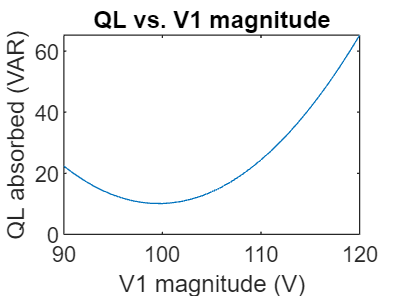

% QL vs. V1 plot
plot(magnitude, QL)
title('QL vs. V1 magnitude')
xlabel('V1 magnitude (V)')
ylabel('QL absorbed (VAR)')

% c) Make comments on the results

% The first plot (almost linear) shows that reactive power is first 
% absorbed (negative) by point 1 before the magnitude of V1 reaches 
% about 99V. Point 1 then delivers reactive power (positive) to the 
% rest of the circuit.

% The second plot (linear) shows that reactive power is first delivered 
% (positive) by point 2 till the magnitude of V1 reaches about 100V. 
% Point 2 then absorbs reactive power (absorbs) from the rest of the circuit.

% The third plot shows that the line impedance only absorbs reactive power 
% (always positive). However, this curve is parabolic where its lowest 
% point is at 10 VAR and about 99-100V. Therefore, when points 1 and 2 
% deliver the least amount of reactive power (from 99V to 100V), the line 
% impedance is capable of absorbing all of the reactive power. This is 
% because both points have similar voltage magnitudes (about 100V) and the
% line impedance is large enough to aborb the small phase difference of 5 
% degrees between the two points.